illustris.utils.set_illUnits(snap);

global illUnits

% read in data
loadFofSub
subsInfo = illustris.infrastructure.build_sub_fof_connection(subs,fofs);
%load('/home/zinger/workProjects/matlab_scripts/IllustrisTNG/matFiles/gasProperties_snp99_TNG100.mat')

% define stellar mass
massAllGals= double(subs.SubhaloMassInRadType(illustris.partTypeNum('stars')+1,:).*illUnits.massUnit); % stellar mass within 2*rhalf

%define host mass

% set mask
massThresh=10^9;
satMask=illustris.infrastructure.generateMask('subs',subs','fofs',fofs,'mass',massThresh,'snap',snap,'sats');
centralMask=illustris.infrastructure.generateMask('subs',subs','fofs',fofs,'mass',massThresh,'snap',snap,'centrals');

r200c=double(fofs.Group_R_Crit200(subsInfo.hostFof+1));
m200c=log10(double(fofs.Group_M_Crit200(subsInfo.hostFof+1).*illUnits.massUnit));




% calculate distance
global LBox
for i=1:3
    dx=abs(double(subs.SubhaloPos(i,:)-fofs.GroupPos(i,subsInfo.hostFof+1)));
    msk=dx>0.5.*LBox;
    
    
    dx(msk)=abs(dx(msk)-LBox);
    
    
    rr(i,:)=dx.^2;
    
    
end

radPosition=sqrt(sum(rr,1))./r200c;
clear rr

% calculate sSFR
ssfr=illustris.utils.calc_ssfr(subs,'base',0);


% bin the distances
binEdges=0.1:0.2:1.5;
binInd=discretize(radPosition,binEdges);
rbin=binEdges(1:end-1)+0.5.*diff(binEdges);

## run with all galaxies - includes ssfr=0

%bin by host mass;
mask11=satMask & m200c>=11 & m200c<12;
mask12=satMask & m200c>=12 & m200c<13;
mask13=satMask & m200c>=13 & m200c<14;
mask14=satMask & m200c>=14 & m200c<15;


ssfrAvg=zeros(4,length(binEdges)-1);

for i=1:length(binEdges)-1
    %mask=mask11 & binInd==i;
    ssfrAvg(1,i)=mean(ssfr(mask11 & binInd==i));
    ssfrAvg(2,i)=mean(ssfr(mask12 & binInd==i));
    ssfrAvg(3,i)=mean(ssfr(mask13 & binInd==i));
    ssfrAvg(4,i)=mean(ssfr(mask14 & binInd==i));
    
end


% add in the obs data

load('/home/zinger/workProjects/matlab_scripts/IllustrisTNG/forDaisuke/ssfr_rpos_dataGrab.mat')
cc=brewermap(8,'Set1');

% centrals 
cmask11=centralMask & m200c>=11 & m200c<12;
cmask12=centralMask & m200c>=12 & m200c<13;
cmask13=centralMask & m200c>=13 & m200c<14;
cmask14=centralMask & m200c>=14 & m200c<15;


ssfrAvgC=zeros(4,1);

%for i=1:length(binEdges)-1
    %mask=mask11 & binInd==i;
    ssfrAvgC(1)=mean(ssfr(cmask11) );
    ssfrAvgC(2)=mean(ssfr(cmask12) );
    ssfrAvgC(3)=mean(ssfr(cmask13) );
    ssfrAvgC(4)=mean(ssfr(cmask14));
    
%end








## plot

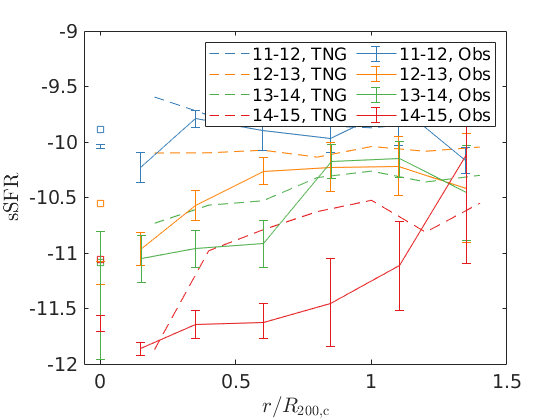


h=[];
figure

for i=1:4
    yy=log10(ssfrAvg(i,:));
    
    switch i
        case 1
            colo=cc(2,:);
            nam='11-12, TNG';
        case 2
            colo=cc(5,:);
            nam='12-13, TNG';
            
        case 3
            colo=cc(3,:);
            nam='13-14, TNG';
            
        case 4
            colo=cc(1,:);
            nam='14-15, TNG';
            
    end
    h(i)=plot(rbin,yy,'color',colo,'DisplayName',nam,"LineStyle","--");
    if i==1; hold on; end
    plot(0,log10(ssfrAvgC(i)),'s','color',colo)
end

 % obs
for i=5:8
        
    switch i
        case 5
            xx=ssfr_rpos_11_main(2,:);
            yy=ssfr_rpos_11_main(1,:);
            pos=ssfr_rpos_11_top(1,:)-ssfr_rpos_11_main(1,:);
            neg=ssfr_rpos_11_main(1,:)-ssfr_rpos_11_bottom(1,:);
            colo=cc(2,:);
            nam='11-12, Obs';
            
            ccc=ssfr_rpos_11_central(1,2);
            cp=ssfr_rpos_11_central(1,3)-ssfr_rpos_11_central(1,2);
            cm=ssfr_rpos_11_central(1,2)-ssfr_rpos_11_central(1,1);
        case 6
            xx=ssfr_rpos_12_main(2,:);
            yy=ssfr_rpos_12_main(1,:);
            pos=ssfr_rpos_12_top(1,:)-ssfr_rpos_12_main(1,:);
            neg=ssfr_rpos_12_main(1,:)-ssfr_rpos_12_bottom(1,:);
            colo=cc(5,:);
            nam='12-13, Obs';
            
            ccc=ssfr_rpos_12_central(1,2);
            cp=ssfr_rpos_12_central(1,3)-ssfr_rpos_12_central(1,2);
            cm=ssfr_rpos_12_central(1,2)-ssfr_rpos_12_central(1,1);
            
        case 7
            xx=ssfr_rpos_13_main(2,:);
            yy=ssfr_rpos_13_main(1,:);
            pos=ssfr_rpos_13_top(1,:)-ssfr_rpos_13_main(1,:);
            neg=ssfr_rpos_13_main(1,:)-ssfr_rpos_13_bottom(1,:);
            colo=cc(3,:);
            nam='13-14, Obs';
            
            ccc=ssfr_rpos_13_central(1,2);
            cp=ssfr_rpos_13_central(1,3)-ssfr_rpos_13_central(1,2);
            cm=ssfr_rpos_13_central(1,2)-ssfr_rpos_13_central(1,1);
            
        case 8
            xx=ssfr_rpos_14_main(2,:);
            yy=ssfr_rpos_14_main(1,:);
            pos=ssfr_rpos_14_top(1,:)-ssfr_rpos_14_main(1,:);
            neg=ssfr_rpos_14_main(1,:)-ssfr_rpos_14_bottom(1,:);
            colo=cc(1,:);
            nam='14-15, Obs';
            
            ccc=ssfr_rpos_14_central(1,2);
            cp=ssfr_rpos_14_central(1,3)-ssfr_rpos_14_central(1,2);
            cm=ssfr_rpos_14_central(1,2)-ssfr_rpos_14_central(1,1);
            
    end
   
    
   
    
    h(i)=errorbar(xx,yy,neg,pos,'color',colo,...
        'DisplayName',nam);
    
        errorbar(0,ccc,cm,cp,'color',colo)
end
    
    set(gca,'fontsize',14)
    hl=legend(h,'numcolumns',2,'location','northeast' );
    
    xlim([-0.06 1.5])
    ylim([-12 -9]) 
     xlabelmine('$r/R_\mathrm{200,c}$');
     ylabelmine('sSFR');